FIX: initial and final gridpoints still are slightly different, fix it (think i fixed this)

FIX: if you scale dt absolutely nothing changes, which is a problem

FIX: M just seems too big (or dt too big)

clear
clc

%1 is Landau Damping
mode = 1;

Nx = 30;
Np = 10000; %Must be even
Ns = 2;
Lx = 4*pi;
c = 1; %speed of light, %%%WARNING: made it 1 for consistency with paper
T0 = 1;
Kb = 1.380649E-23; %boltzmann constant, %%%WARNING: made it 1 for consistency with paper (or not)
rho0 = 1;

q0 = 1;
e0 = 1; %permittivity of free space, %%%WARNING: made it 1 for consistency with paper
m_electron = 1;
m_ion = 2000;

x = zeros(Np, 3);
v = zeros(Np, 3);
vt = zeros(Np, 3);
alpha = cell(Np, 1);
Bp = zeros(Np, 3);
Ep = zeros(Np, 3);

t_max = 15;
dt = 0.5;
E = zeros(Nx, 3);
Et = zeros(Nx, 3);
B = zeros(Nx, 3);
Bt = zeros(Nx, 3);
J = zeros(Nx, 3); %It's J with a curved hat in the paper

M = cell(Nx, Nx);
for i = 1:Nx
    for j = 1:Nx
        M{i, j} = zeros(3,3);
    end
end

store_electric_field = false;

Mode specific initialization

dx = Lx/Nx;
t = 0;

if(mode == 1)
    v_max_electron = 8;
    v_max_ion = 0.002;
    Lx = 4*pi;
    m = [ones(Np/2, 1)*m_electron; ones(Np/2, 1)*m_ion];
    q(1:Np/2,1) = -q0/m_electron*m(1:Np/2,1); 
    q(Np/2+1:Np,1) = q0/m_ion*m(Np/2+1:Np,1);
    scaling = rho0*Lx/sum(abs(q)); %maybe times dx^3 or whatever, not sure if sum of q or m
    m = m*scaling;
    q = q*scaling;
    x(:,1) = rand(Np,1)*Lx;
    a_electrons = m(1)/(2*Kb*T0);
    a_ions = m(length(m)-1)/(2*Kb*T0);
    v(1:Np/2,1) = sat(boltzmann(a_electrons, Np/2), v_max_electron);
    v(Np/2+1:Np,1) = sat(boltzmann(a_ions, Np/2), v_max_ion);
    E(:,1) = -0.2*sin(linspace(0,Lx,Nx)/2);
    B = zeros(size(B));
    %E(:,1) = ones(Nx, 1);
    store_electric_field = true;
    store_kinetic_energy = true;
    Eh = zeros(Nx,0);
    Ke = zeros(Nx,0);
end

Construct Matrices

beta = q./m*(dt/2);
c1 = 1/(2*dx);
c2 = 2/(c*dt);
c3 = 4*pi/c;

C1 = zeros(6, 6);
C1(2,6) = c1;
C1(3,5) = -c1;
C1(5,3) = c1;
C1(6,2) = -c1;
C2 = diag([-c2, -c2, -c2, c2, c2, c2]);
C3 = -C1;

A = zeros(6*Nx, 6*Nx); %A is the system matrix without the mass terms

for i = 1:6:Nx*6
    j = mod(i-6, 6*Nx);
    k = mod(i+6, 6*Nx);
    A(i:i+5,i:i+5) = C2;
    A(i:i+5, j:j+5) = C1;
    A(i:i+5, k:k+5) = C3;
end
% A = sparse(A);

Af = zeros(6*Nx, 6*Nx); %Af will be the full system matrix
C = zeros(6*Nx, 1); %C will be the system vector

Time advancement

tic
%outer loop
while (t < t_max)
    if(store_electric_field)
        Eh = [Eh, E(:,1)];
    end
    if(store_kinetic_energy)
        Ke = [Ke, 0.5*sum(m.*(v(:,1).*v(:,1)+v(:,2).*v(:,2)+v(:,3).*v(:,3)))];
    end
    %Step 1
    x = x + dt*v;
    %Periodic boundary condition
    x(:,1) = mod(x(:,1),Lx);
    %Step 2
    Bp = [evaluateField(B(:,1), x, Lx, Nx), evaluateField(B(:,2), x, Lx, Nx), evaluateField(B(:,3), x, Lx, Nx)];
    %Step 3
    for i = 1:Np
        alpha{i} = evaluateAlpha(beta(i), Bp(i,:));
    end
    %Step 4:::test thiss
    %Empty currents
    for g = 1:Nx
        J(g,:) = 0;
    end
    for p = 1:Np
        %g is zero indexed in this loop
        g = getParticleGridCell(x(p,1), Lx, Nx);
        J(g+1,:) = J(g+1,:) + (q(p)*alpha{p}*v(p,:)'*evaluateWeigth(x(p,1), g, Lx, Nx))';
        J(mod(g+1,Nx)+1,:) = J(mod(g+1,Nx)+1,:) + (q(p)*alpha{p}*v(p,:)'*evaluateWeigth(x(p,1), mod(g+1,Nx), Lx, Nx))';
    end
    %Step 5
    %Empty mass matrices
    for g = 1:Nx
        for gp = 1:Nx
            M{g, gp} = zeros(3,3);
        end
    end
    %Compute mass matrices:::test thiss
    for p = 1:Np
        %g is zero indexed in this loop
        g = getParticleGridCell(x(p,1), Lx, Nx);
        k = beta(p)/dx*q(p)*alpha{p}*...
            evaluateWeigth(x(p,1), g, Lx, Nx)*evaluateWeigth(x(p,1), mod(g+1, Nx), Lx, Nx);
        M{g+1, mod(g+1,Nx)+1} = M{g+1, mod(g+1,Nx)+1} + k;
        M{mod(g+1,Nx)+1, g+1} =  M{mod(g+1,Nx)+1, g+1} + k;
        M{g+1, g+1} = M{g+1, g+1} + beta(p)/dx*q(p)*alpha{p}*...
            evaluateWeigth(x(p,1), g, Lx, Nx)^2;
        M{mod(g+1,Nx)+1, mod(g+1,Nx)+1} = M{mod(g+1,Nx)+1, mod(g+1,Nx)+1} + ...
        beta(p)/dx*q(p)*alpha{p}*evaluateWeigth(x(p,1), mod(g+1, Nx), Lx, Nx)^2;
        %%%%%% WHY have I not done g+1 to g+1 effectttt????? 
    end
    %Compute system vector
    Af = A; %Base matrix
    for i = 1:Nx %Add mass terms
        j = mod(i-2,Nx)+1;
        k = mod(i,Nx)+1;
        Af(6*i-5:6*i-3, 6*i-5:6*i-3)=Af(6*i-5:6*i-3, 6*i-5:6*i-3)-c3*M{i,i};
        Af(6*i-5:6*i-3, 6*k-5:6*k-3)=Af(6*i-5:6*i-3, 6*k-5:6*k-3)-c3*M{i,k};
        Af(6*i-5:6*i-3, 6*j-5:6*j-3)=Af(6*i-5:6*i-3, 6*j-5:6*j-3)-c3*M{i,j};
    end
    %Compute system vector
    C = c2*reshape([-E,B]',[6*Nx,1]); %En and Bn terms
    C = C + c3*reshape([J,zeros(Nx,3)]',[6*Nx,1]); %current terms
    %Solve system
    sol = reshape(linsolve(Af,C),[6,Nx]);
    %Extract half-time fields
    Et = sol(1:3,1:Nx)';
    Bt = sol(4:6,1:Nx)';
    %Step 7
    Ep = [evaluateField(Et(:,1), x, Lx, Nx), evaluateField(Et(:,2), x, Lx, Nx), evaluateField(Et(:,3), x, Lx, Nx)];
    %Step 8
    for i = 1:Np
        vt(i,:) = alpha{i}*(v(i,:)'+beta(i)*Ep(i,:)');
    end
    v = 2*vt - v;
    %Update fields
    E = 2*Et-E;
    B = 2*Bt-B;
    t = t + dt;
end
toc

Elapsed time is 5.865362 seconds.


Plot electric field variation

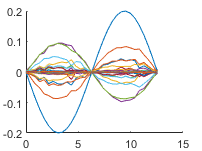

figure(1);
clf
hold on
for i = 1:size(Eh, 2)
    plot(linspace(0,Lx,Nx), Eh(:,i));
end

Plot electric field energy in time

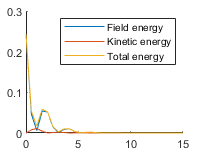

figure(2);
clf
hold on
energy = [];
for i = 1:size(Eh, 2)
    energy = [energy, dx*sum(Eh(:,i).*Eh(:,i))]; %%%%WARNING, formula should be /e0 inside but ignore for last year comparison
end
plot(linspace(0, t, size(Eh, 2)), energy);
plot(linspace(0, t, size(Eh, 2)), Ke);
plot(linspace(0, t, size(Eh, 2)), energy + Ke);
legend('Field energy', 'Kinetic energy', 'Total energy');

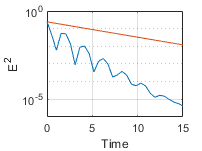

%plot(0:dt:t_max, energy);

figure(3);
clf
semilogy(linspace(0, t, size(Eh, 2)), energy);
hold on
semilogy(linspace(0, t, size(Eh, 2)), energy(1)*exp(-0.2*linspace(0, t, size(Eh, 2))));
grid on
xlabel('Time')
ylabel('E^{2}')

Evaluate field

Fix for periodic condition

function F = evaluateField(field, x, Lx, Nx)
    f = fit(linspace(0,Lx,Nx+1)', [field; field(1,:)], 'Linear');
    F = f(x);
end


Particle grid cell

%Returns 0 indexedddd
function g = getParticleGridCell(x, Lx, Nx)
    dx = Lx/Nx;
    g = floor(x/dx);
end

Evaluate Wpg

%%%g is 0 indexedddd
function W = evaluateWeigth(xp, g, Lx, Nx)
    dx = Lx/Nx;
    xg = g*dx;
    %Periodic condition
    if(g==0 && xp+dx>Lx)
        W = 1 - abs(Lx-xp)/dx;
        return;
    end
    if (xp < xg - dx || xp > xg + dx)
        W = 0;
    else
        W = 1 - abs(xp-xg)/dx;
    end
end

Alpha: TOOK FROM GIOVANNI LAPENTA (REFERENCEEEE)

function alpha = evaluateAlpha(beta, B)
Bx = B(1);
By = B(2);
Bz = B(3);

sx=Bx*beta;sy=By*beta;sz=Bz*beta;
alpha=[1+sx*sx  sz+sx*sy   -sy+sx*sz;
      -sz+sx*sy  1+sy*sy   sx+sy*sz;
      sy+sx*sz   -sx+sy*sz    1+sz*sz]/(1+sx*sx+sy*sy+sz*sz);
end


Generate 1D maxwell boltzmann distribution

function y = boltzmann(a, n)
    x = rand([1,n]);
    y = erfinv(2*x-1)/sqrt(a); 
end

Saturation funtion (to +- delta)

function y = sat(x, delta)
   y = min(max(x, -delta), delta); 
end